# Define Import Options Object to Read Fixed-Width Text File

Examine a fixed-width formatted text file, initialize an import options object, and use the object to import the table from the text file.

## Load and Preview  Fixed-Width Text File

Load the file `fixed_width_patients_subset_perfect.txt` and preview its contents in a text editor. The screen shot shows that the file contains fixed-width formatted data.

filename = 'fixed_width_patients_subset_perfect.txt';

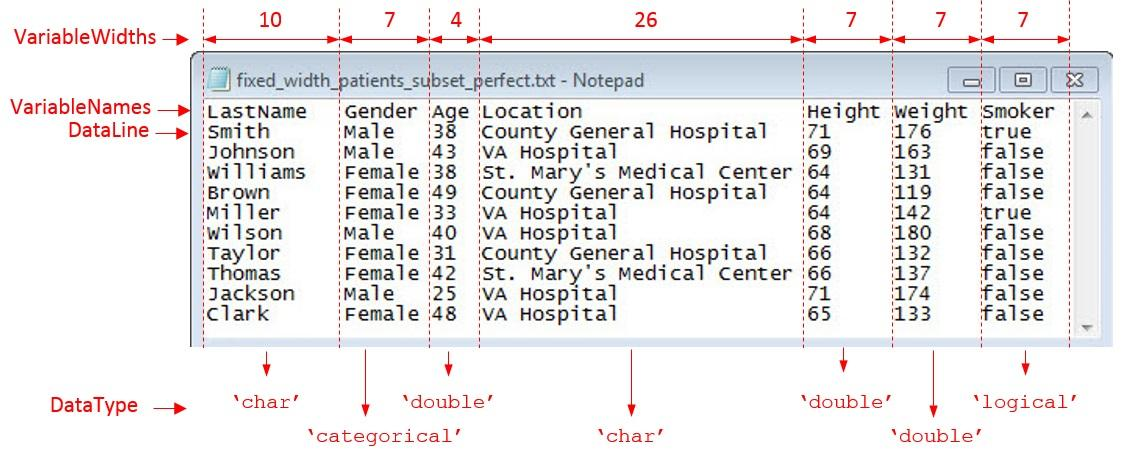

## Examine and Extract Properties of Fixed-Width File

The fixed-width text file has tabular data organized by starting location, number of variables, variable names, and variable widths. Capture these properties and the desired data type for the variables.

DataStartLine = 2;
NumVariables = 7;
VariableNames  = {'LastName','Gender','Age','Location','Height',...
                                                      'Weight','Smoker'};
VariableWidths = [ 10,     7,     4,    26,     7, ...
                                                         7,     7 ] ;                                                  
DataType       = {'char','categorical','double','char','double',...
                                                     'double','logical'};


## Initialize and Configure  `FixedWidthImportOptions` Object

Initialize a `FixedWidthImportOptions` object and configure its properties to match the properties of the data in  `fixed_width_patients_subset_perfect.txt`.

opts = fixedWidthImportOptions('NumVariables',NumVariables,...
                               'DataLines',DataStartLine,...
                               'VariableNames',VariableNames,...
                               'VariableWidths',VariableWidths,...
                               'VariableTypes',DataType);

## Import Table

Use `readtable` with the `FixedWidthImportOptions` object to import the table.

T = readtable(filename,opts)

*Copyright 2012 The MathWorks, Inc.*